# [Q6] MUTUAL COUPLING

Created by: Prof F Gonzalez-Longatt, 09.02.2019 

Document available at: [ResearchGate](https://www.researchgate.net/publication/338076702_TUTORIAL_Ideal_Two-winding_power_transformer)

DOI: [10.13140/RG.2.2.16327.85923](https://www.researchgate.net/deref/http%3A%2F%2Fdx.doi.org%2F10.13140%2FRG.2.2.16327.85923?_sg%5B0%5D=YODqr8lUC06krCLuHg1BoE9mY5qezkWzIUxCV0DmGjNNAkt2ko2S-K7aAl_WeMflGHrpPVcu4nEDH629k7MCVMvPJA.mVSFRNpv-yDPME3Qi57BQAKClwG3aAfLKwxRKAIXYpZGKw0ppLSDza4McWefQVZnxzztkv2edvlMMY5RYXLBVw)

[Q6] In Fig. Q.6, V. Find the (a) phasor current in the primary (I1) and secondary (I2) circuits (b) the phasor voltages across the inductors in the primary (V11’) and (V22’) secondary circuits c) the turns ratio. 

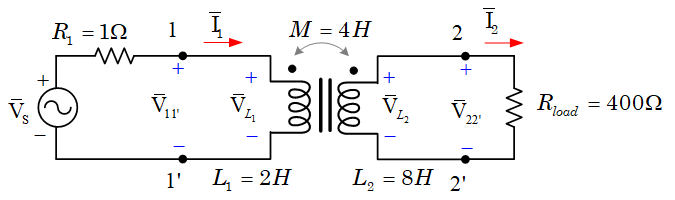

Figure [Q6]: 

%(Hint: the voltages across the inductors are the vector sum of the self 
% AND mutually induced voltages). Assuming w =  10 rad/sec.
clc
clear
fprintf(' SOLUTION \n')

 SOLUTION 


## INPUT DATA

Vs = 10 * exp(+ i * 0 * pi/180); % Vs: Supply voltage in volts (polar form)
w = 10;                          % w: angular speed in radian/secodns
L1 = 2;                          % L1: self-inductance, L1 in Henry
L2 = 8;                          % L2: self-inductance, L1 in Henry
M = 4;                           % M: Mutual-inductance, L1 in Henry
R1 = 1;                          % R1: Resistance -seriees- located in the primary in Ohms
Rload = 400;                     % Rload: Load resistance in Ohms

## Calculating the reactances (XL1, XL2, XM)

The time-domain data is transformed into phasor-domain

XL1 = w * L1;                   % XL1: Primeary self-inductive reactance
XL2 = w * L2;                   % XL2: Secundary self-inductive reactance
XM = w * M;                     % XM: Mutual-inductive reactance

## Calculating coupling coefficient (k)

The *coupling coefficient* (*k*) is:

k = M/sqrt(L1*L2);              % K: Coupling coefficient...
fprintf(' k = %5.4f \n',k);

 k = 1.0000 


## Calculating the current (I1 and I2)

Creating the Impedance matrix (Zbus). Using the Kirchoff voltage law (KVL)

Zmatrix = [(R1 + i * XL1)   -i * XM; ...
    -i * XM  (Rload + i * XL2)];
% Creating voltage vector (VV)
Vvector = [Vs ; 0];
% Calculating current using Ohms law: I = V/Z
% Solving the set of lineal equations:
I = Zmatrix^-1 * Vvector;
I1 = I(1);  % I1
I2 = I(2);  % I2

## Printing results:

fprintf(' CURRENTS \n') 

 CURRENTS 


fprintf(' I1 = (%5.4f + %5.4fj) A  (rectangular form) \n',real(I1),imag(I1))

 I1 = (0.1232 + -0.4889j) A  (rectangular form) 


fprintf(' I1 = (%5.4f < %5.4f) A (polar form) \n',abs(I1),angle(I1)*180/pi)

 I1 = (0.5042 < -75.8560) A (polar form) 


%========================================================================
fprintf(' I2 = (%5.4f + %5.4fj) A (rectangular form) \n',real(I2),imag(I2))

 I2 = (0.0494 + 0.0024j) A (rectangular form) 


fprintf(' I2 = (%5.4f < %5.4f) A (polar form) \n',abs(I2),angle(I2)*180/pi)

 I2 = (0.0494 < 2.8341) A (polar form) 


## Calculation primary (V1) and Secundary (V2) voltages

V1 =  i * XL1 * I1 -  i * XM * I2;
V2 = Rload * I2;
a = abs (V1/V2);

## Printing voltages results:

fprintf(' VOLTAGES \n') 

 VOLTAGES 


fprintf(' V1 = (%5.4f + %5.4fj) V (rectangular form) \n',real(V1),imag(V1))

 V1 = (9.8768 + 0.4889j) V (rectangular form) 


fprintf(' V1 = (%5.4f < %5.4f) V (polar form) \n',abs(V1),angle(V1)*180/pi)

 V1 = (9.8889 < 2.8341) V (polar form) 


%========================================================================
fprintf(' V2 = (%5.4f + %5.4fj) V (rectangular form) \n',real(V2),imag(V2))

 V2 = (19.7536 + 0.9779j) V (rectangular form) 


fprintf(' V2 = (%5.4f < %5.4f) V (polar form) \n',abs(V2),angle(V2)*180/pi)

 V2 = (19.7778 < 2.8341) V (polar form) 
